# Matlab Graph Titling, Labels and Legends Examples

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

## **Draw A figure Label Title, X and Y Axises with Latex Equations**

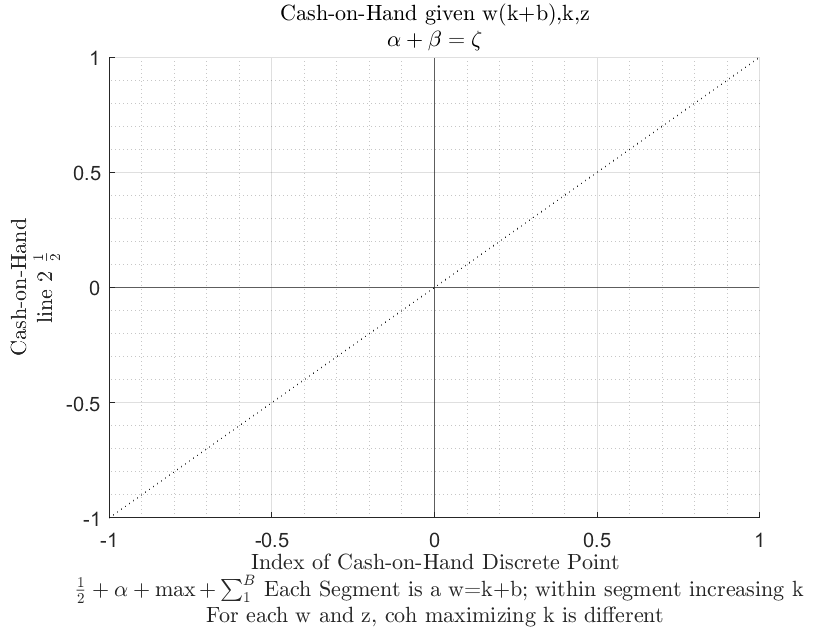

clear all;
close all;
figure();

% draw some lines
xline0 = xline(0);
xline0.HandleVisibility = 'off';
yline0 = yline(0);
yline0.HandleVisibility = 'off';
hline = refline([1 0]);
hline.Color = 'k';
hline.LineStyle = ':';
hline.HandleVisibility = 'off';

% Titling with multiple lines
title({'Cash-on-Hand given w(k+b),k,z' '$\alpha + \beta = \zeta$'},'Interpreter','latex');
ylabel({'Cash-on-Hand' 'line 2 $\frac{1}{2}$'},'Interpreter','latex');
xlabel({'Index of Cash-on-Hand Discrete Point'...
        ' $\frac{1}{2} + \alpha + \max + \sum_1^{B}$ Each Segment is a w=k+b; within segment increasing k'...
        'For each w and z, coh maximizing k is different'},'Interpreter','latex');
grid on;
grid minor;

## Matlab Graph Specify Legends Manually

Specify labels manually, note we can use HandleVisibility to control what part of figure show up in legends.

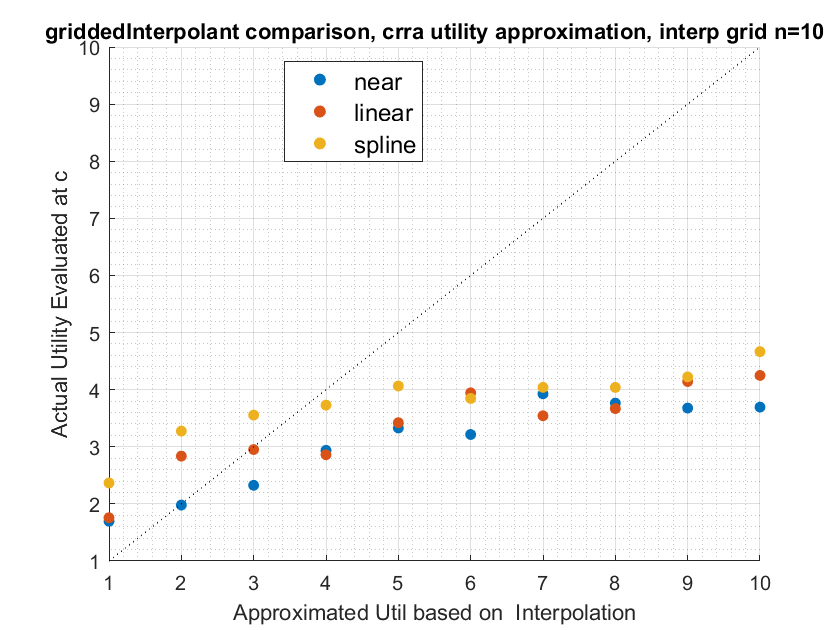

% Generate Random Data
rng(123);
it_x_n = 10;
it_x_groups_n = 3;
mat_y = rand([it_x_n, it_x_groups_n]);
mat_y = mat_y + sqrt(1:it_x_groups_n);
mat_y = mat_y + log(1:it_x_n)';
ar_x = 1:1:it_x_n;

% Start Figure
figure('PaperPosition', [0 0 10 10]);

hold on;

g1 = scatter(ar_x,  mat_y(:,1), 30, 'filled');
g2 = scatter(ar_x,  mat_y(:,2), 30, 'filled');
g3 = scatter(ar_x,  mat_y(:,3), 30, 'filled');

legend([g1, g2, g3], {'near','linear','spline'}, 'Location','best',...
        'NumColumns',1,'FontSize',12,'TextColor','black');

% PLot this line, but this line will not show up in legend
hline = refline([1 0]);
hline.Color = 'k';
hline.LineStyle = ':';
% not to show up in legend
hline.HandleVisibility = 'off';
grid on;
grid minor;

title(sprintf('griddedInterpolant comparison, crra utility approximation, interp grid n=%d', it_x_n))
ylabel('Actual Utility Evaluated at c')
xlabel('Approximated Util based on  Interpolation')

snapnow;

## Given Graph, Graph Subset of Lines and Add Extra Line with Legend

Same plot as before, except we plot only 2 of the three lines and add another line with associated legend entry.

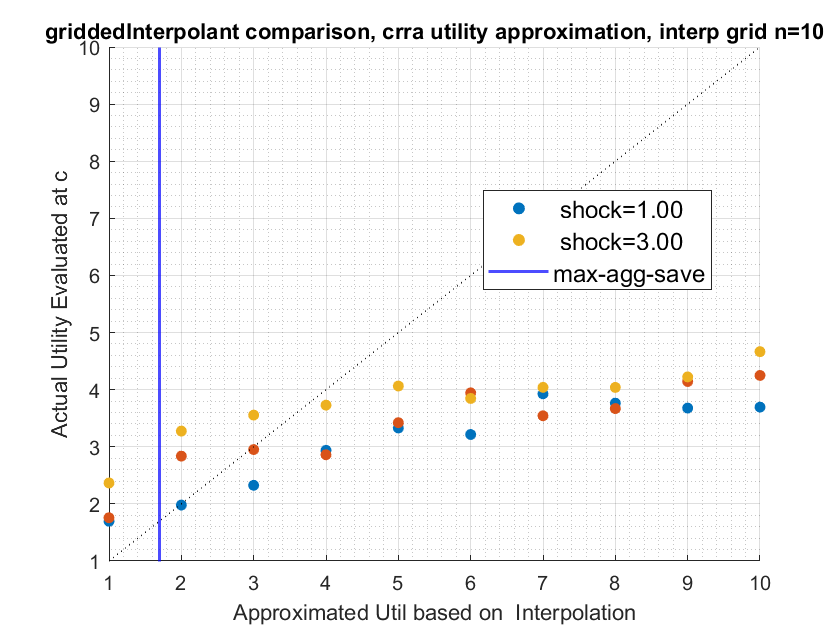

legendCell = cellstr(num2str(ar_x', 'shock=%3.2f'));
xlinemax = xline(min(mat_y, [], 'all'));
xlinemax.Color = 'b';
xlinemax.LineWidth = 1.5;

legendCell{length(legendCell) + 1} = 'max-agg-save';
legend([g1, g3, xlinemax], legendCell([1,3,length(legendCell)]), 'Location', 'best');

snapnow;